R1 = 50;
C1 = 20E-6;
R2 = 5000;
C2 = 1E-9;

a = R1*R2*C1*C2;
b = (R1+R2)*C1 + R2*C2;
c = R2*C1;

G = tf([c 0], [a b 1])

G =
 
           0.1 s
  -----------------------
  5e-09 s^2 + 0.101 s + 1
 
Continuous-time transfer function.



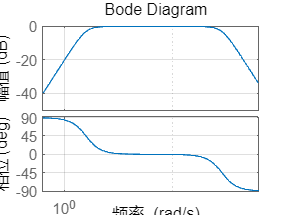

figure()
bode(G);
grid on;

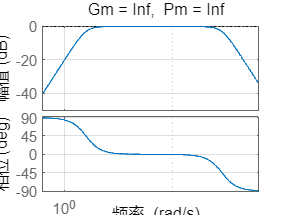


figure()
margin(G);
grid on;


delta = b^2 - 4*a*1;
% cut-off frequency
f1 = (-b + sqrt(delta)) / (2*a) / (2*pi)

f1 = -1.5757

f2 = (-b - sqrt(delta)) / (2*a) / (2*pi)

f2 = -3.2151e+06


f0 = sqrt(f1*f2)

f0 = 2.2508e+03

sqrt(1/a) / (2*pi)

ans = 2.2508e+03

% gain at center
mag2db((c.*f0) ./ sqrt( (1-a.*f0.^2).^2 + b^2.*f0.^2 ))

ans = -0.0869

mag2db(c / b)

ans = -0.0869

## 手动计算Bode

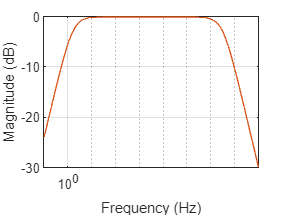

[mag, phase, wout] = bode(G);
figure
semilogx(wout/(2*pi), mag2db(mag(:)))
grid on;
xlabel("Frequency (Hz)");
ylabel("Magnitude (dB)");
xlim([0.1 100E6])
hold on;
% g_cal = c.*wout ./ sqrt((1-a.*wout.^2).^2 + (b.*wout).^2)

semilogx(wout/(2*pi), mag2db(Gain_cal(wout/(2*pi), a, b, c)))

fin = 761E3;
A0 = 1.8

A0 = 1.8000

Ain = A0*Gain_cal(fin, a, b, c)

Ain = 1.7342

mag2db(Gain_cal(fin, a, b, c))

ans = -0.3236


% w = logspace(0, 9)
% gain = (c.*w) ./ sqrt( (1-a.*w.^2).^2 + b^2.*w.^2 );
% gain_db = mag2db(gain);
% figure
% semilogx(w ./(2*pi), gain_db);
% grid on
% 
Para_R([1 1])

ans = 0.5000

function Rout = Para_R(Rin)
    G = 1 ./ Rin;
    Gout = sum(G);
    Rout = 1/Gout;
end

function Gain = Gain_cal(fin, a, b, c)
    win = 2.*pi*fin;
    Gain = c.*win ./ sqrt((1-a.*win.^2).^2 + (b.*win).^2);
end